     0     0

   -0.3673   -0.3061

   -0.7347   -0.6122

   -1.1020   -0.9184

   -1.4694   -1.2245

   -1.8367   -1.5306

   -2.2041   -1.8367

   -2.5714   -2.1429

   -2.9388   -2.4490

   -3.3061   -2.7551

   -3.6735   -3.0612

   -4.0408   -3.3673

   -4.4082   -3.6735

   -4.7755   -3.9796

   -5.1429   -4.2857

   -5.5102   -4.5918

   -5.8776   -4.8980

   -6.2449   -5.2041

   -6.6122   -5.5102

   -6.9796   -5.8163

   -7.3469   -6.1224

   -7.7143   -6.4286

   -8.0816   -6.7347

   -8.4490   -7.0408

   -8.8163   -7.3469

   -9.1837   -7.6531



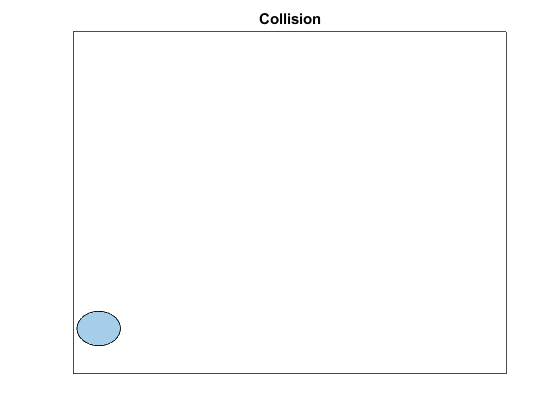

c1 = circle;
c2 = circle;
c3 = circle;
x = [1 0];
y = [0 1];
[v1,b1,v2,b2,v3,b3] = generateRandomV(3);
for i = linspace(0,3,50)
    c1.polygon = translate(polyshape(c1.xdata,c1.ydata),v1*i);
    disp(v1*i)
%     c2.polygon = translate(polyshape(c2.xdata,c2.ydata),v2*i);
%     c3.polygon = translate(polyshape(c3.xdata,c3.ydata),v3*i);
    if detectCollision(c1) == true
        title('Collision')
        break
%     elseif detectCollision(c2,c3) == true
%         title('Collision')
%         break
%     elseif detectCollision(c1,c3) == true
%         title('Collision')
%         break
    end
    renderer(c1.polygon)
end